%path and some parameters
addpath(genpath('Z:/GRABS_Data/Code/meso_processing-master'));
addpath(genpath('F:\Sweyta\GRABS_Data\BackScatter'));
rmpath(genpath('Z:\GRABS_Data\Code\meso_processing-master\chronux_2_12')); 
inputPath= 'F:\Sweyta\GRABS_Data\BackScatter';
outputPath='Z:\GRABS_Data\Analyzed_SVDMethodPatch14\BackScatterOutput';
fsspike2=5000;
fsimaging=10;

Parcellatingblue
Parcellatinguv
Parcellatinggreen
ParcellatingBS1


Reference to non-existent field 'BS1'.

pupilSR=10;
deterend.filtLen = 1000;
% visusal stim
visStimAn=1; % 1 if vis stim are presented, 0 if not
airpuffAn=0; % if airpuffs or electrical stim are presented, indicate 1;
visStimDur=2;
visStimITI=5;
%run params
minRunDuration=5; %in seconds
minSitDuration=10; %in seconds

Parcellatingblue
Parcellatinguv
Parcellatinggreen
ParcellatingBS1
ParcellatingBS2


Reference to non-existent field 'BS2'.

ITITime=5; %  dead time after events in seconds
%analysis window for events (airpuff and visstim)
preEventWin=2;
postEventWin=5;
baselineWin=2; %use this period to calculate baseline during within trial normalization
% spike2 channels for bcmm
channels.BLUE = 1;%blue led
channels.UV = 2;%uv led
channels.GREEN=9;%green LED

Parcellatingblue
Parcellatinguv
Parcellatinggreen
ParcellatingBS1


Reference to non-existent field 'BS1'.

channels.BS1=6; 
channels.BS2=10
channels.FRAMETICKS = 8;%green/uv mesocam triggers
channels.PHOTO_DIODE = 4;%visual stim trigger
channels.WHEEL = 5;
channels.PUPIL_CAMERA = 7;
channels.RED_MESO = 3;%red mesocam trigger


Parcellatingblue
Parcellatinguv
Parcellatinggreen
ParcellatingBS1


## Method 1: Uncorrected load uncorrected dF/F


load(fullfile(outputPath,'dFOF_Uncorrected.mat'));
%get dFoF parcells
names=fieldnames(dFoF);
load('parcells_updated121519.mat'); parcells=parcells_new;
for i = 1:length(names)
    disp(['Parcellating' names{i}]);
    dFoF_parcells.(names{i}) = pixels2rois(dFoF.(names{i}), parcells);

Parcellatingblue
Parcellatinguv
Parcellatinggreen
ParcellatingBS1
ParcellatingBS2


end

## Method 2: Hadas SVD against UV


load(fullfile(outputPath,'dFOF_SVD_UV_nosmooth.mat'));
%get dFoF parcells
for i = 1:length(names)
    if ~isfield(dFoF_SVD_UV,names{i}),continue,end 
    disp(['Parcellating' names{i}]);
    dFoF_SVD_UV_parcells.(names{i}) = pixels2rois(dFoF_SVD_UV.(names{i}), parcells);
end

Parcellatingblue
Parcellatinguv
Parcellatinggreen
ParcellatingBS1
ParcellatingBS2


## Method 3: Hadas SVD against BS1

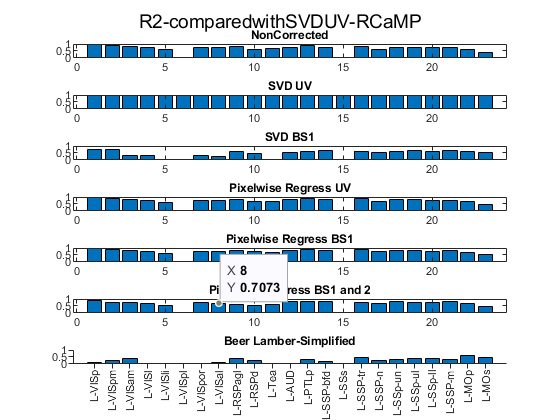

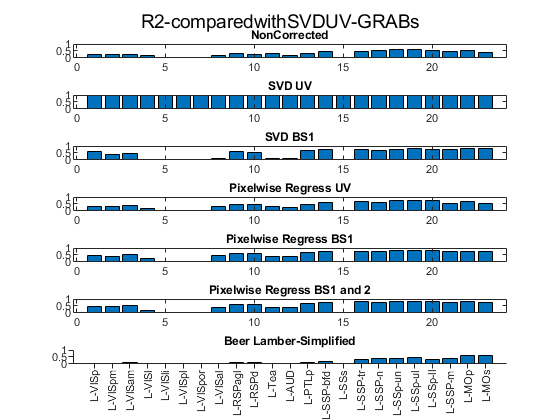

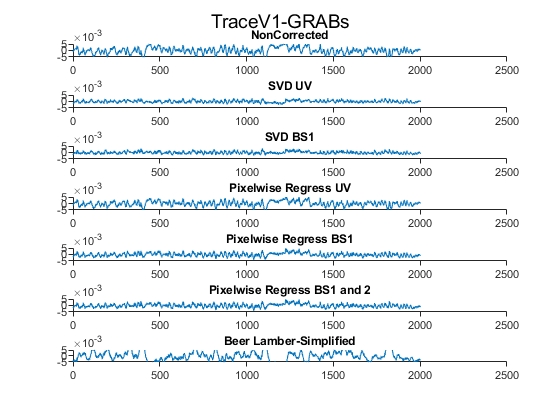

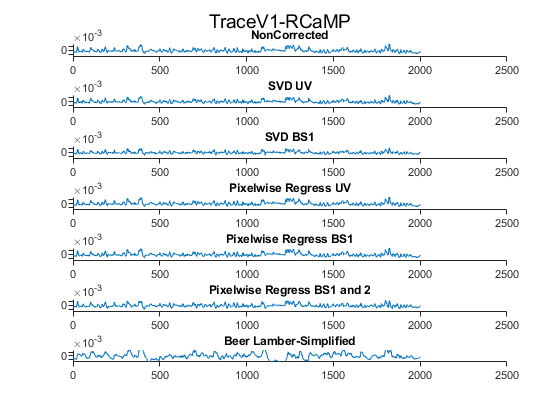

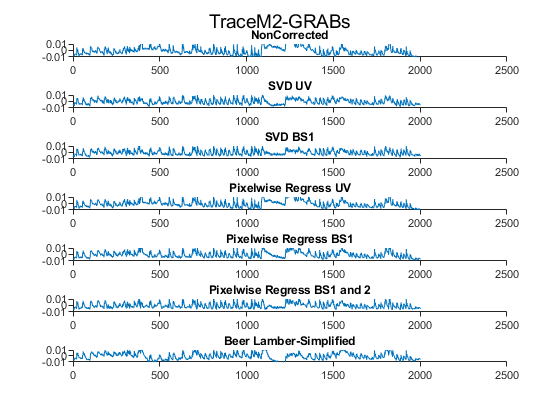

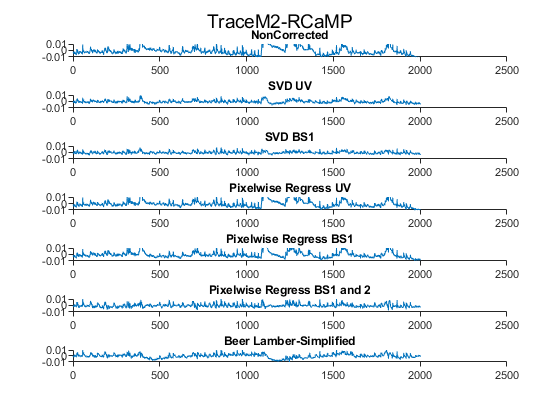

loading spike 2 file:F:\Sweyta\GRABS_Data\BackScatter\07012020_grab09_backscatter.smrx


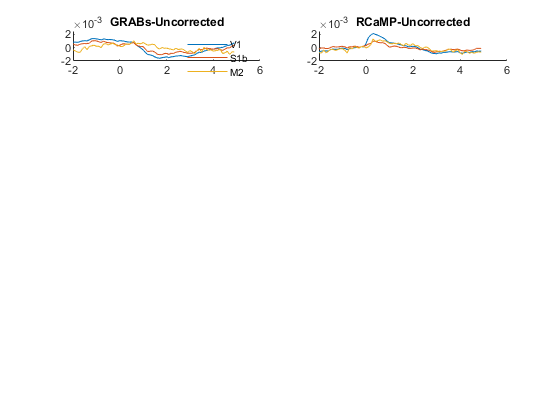

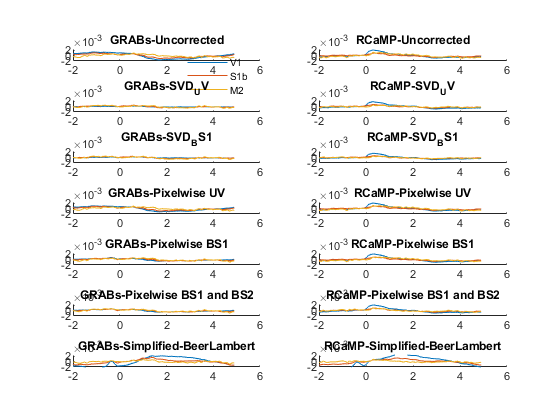


load(fullfile(outputPath,'dFOF_SVD_BS1_nosmooth.mat'));

%get dFoF parcells
for i = 1:length(names)
    if ~isfield(dFoF_SVD_BS1,names{i}),continue,end 
    disp(['Parcellating' names{i}]);
    dFoF_SVD_BS1_parcells.(names{i}) = pixels2rois(dFoF_SVD_BS1.(names{i}), parcells);
end

## Method 4: pixelwise regression against UV

load(fullfile(outputPath,'dFOF_PixUV_nosmooth.mat'));
%get dFoF parcells
for i = 1:length(names)
    if ~isfield(dFoF_PixUV,names{i}),continue,end 
    disp(['Parcellating' names{i}]);
    dFoF_PixUV_parcells.(names{i}) = pixels2rois(dFoF_PixUV.(names{i}), parcells);
end

## Method 5: pixelwise regression against BS1


load(fullfile(outputPath,'dFOF_PixBS1_nosmooth.mat'));
%get dFoF parcells
for i = 1:length(names)
    if ~isfield(dFoF_PixBS1,names{i}),continue,end 
    disp(['Parcellating' names{i}]);
    dFoF_PixBS1_parcells.(names{i}) = pixels2rois(dFoF_PixBS1.(names{i}), parcells);
end


## Method 6: pixelwise regression against BS1 and BS2

load(fullfile(outputPath,'dFOF_PixBS12_nosmooth.mat'));
%get dFoF parcells
for i = 1:length(names)
    if ~isfield(dFoF_PixBS12,names{i}),continue,end 
    disp(['Parcellating' names{i}]);
    dFoF_PixBS12_parcells.(names{i}) = pixels2rois(dFoF_PixBS12.(names{i}), parcells);
end

## Method 7: Beer Lambert model (Waters and Hillman paper)

load(fullfile(outputPath,'dFOF_BLam_nosmooth.mat'));
%get dFoF parcells
for i = 1:length(names)
    if ~isfield(dFoF_BLam,names{i}),continue,end 
    disp(['Parcellating' names{i}]);
    dFoF_BLam_parcells.(names{i}) = pixels2rois(dFoF_BLam.(names{i}), parcells);
end


%%calculate R2 comparing traces for V1, S1, and M2 parcells across methods
%%comapre all to the SVD against UV method 
Idx.visual=2:2:16; %visual parcells
Idx.PosteriorParietal=32;% PPC
Idx.RSL_AgL=[18,20];%retrosplenial cortex
Idx.Somat=34:2:48;%somatosensory areas
Idx.FrontalMotor=50:2:52;%frontal-moto area
Idx.auditory=[28,30];%auditory areas
CombinedParcellIdx=[Idx.visual,Idx.RSL_AgL,Idx.auditory,Idx.PosteriorParietal,Idx.Somat,Idx.FrontalMotor];

names={'blue','green'};
for i=1:length(names)
    for j=1:length(parcells.names)
        R2_par.(names{i})(j,1)=corr(dFoF_parcells.(names{i})(j,:)',dFoF_SVD_UV_parcells.(names{i})(j,:)').^2; %method 1 uncorrected
        R2_par.(names{i})(j,2)=corr(dFoF_SVD_UV_parcells.(names{i})(j,:)',dFoF_SVD_UV_parcells.(names{i})(j,:)').^2; %method 2 SVD UV
        R2_par.(names{i})(j,3)=corr(dFoF_SVD_BS1_parcells.(names{i})(j,:)',dFoF_SVD_UV_parcells.(names{i})(j,:)').^2; %method 3 SVD BS1
        R2_par.(names{i})(j,4)=corr(dFoF_PixUV_parcells.(names{i})(j,:)',dFoF_SVD_UV_parcells.(names{i})(j,:)').^2; %method 4 pixelwise uv regression
        R2_par.(names{i})(j,5)=corr(dFoF_PixBS1_parcells.(names{i})(j,:)',dFoF_SVD_UV_parcells.(names{i})(j,:)').^2; %method 5 pixelwise BS1 regression
        R2_par.(names{i})(j,6)=corr(dFoF_PixBS12_parcells.(names{i})(j,:)',dFoF_SVD_UV_parcells.(names{i})(j,:)').^2; %method 6 pixelwise BS1 and BS2 regression
        R2_par.(names{i})(j,7)=corr(dFoF_BLam_parcells.(names{i})(j,:)',dFoF_SVD_UV_parcells.(names{i})(j,:)').^2; %method 7 beer lambert model 
    end    
    
end
figure; suptitle('R2-comparedwithSVDUV-GRABs');
subplot(7,1,1);bar(R2_par.blue(CombinedParcellIdx,1)); ylim([0 1]); title('NonCorrected');
subplot(7,1,2);bar(R2_par.blue(CombinedParcellIdx,2)); ylim([0 1]); title('SVD UV')
subplot(7,1,3);bar(R2_par.blue(CombinedParcellIdx,3)); ylim([0 1]); title('SVD BS1')
subplot(7,1,4);bar(R2_par.blue(CombinedParcellIdx,4)); ylim([0 1]); title('Pixelwise Regress UV')
subplot(7,1,5);bar(R2_par.blue(CombinedParcellIdx,5)); ylim([0 1]); title('Pixelwise Regress BS1')
subplot(7,1,6);bar(R2_par.blue(CombinedParcellIdx,6)); ylim([0 1]); title('Pixelwise Regress BS1 and 2')
subplot(7,1,7);bar(R2_par.blue(CombinedParcellIdx,7)); ylim([0 1]); title('Beer Lamber-Simplified');xticks(1:length(CombinedParcellIdx));xticklabels(parcells.names(CombinedParcellIdx));xtickangle(90);box off; set(gca,'TickDir','out')

figure; suptitle('R2-comparedwithSVDUV-RCaMP');
subplot(7,1,1);bar(R2_par.green(CombinedParcellIdx,1)); ylim([0 1]); title('NonCorrected');
subplot(7,1,2);bar(R2_par.green(CombinedParcellIdx,2)); ylim([0 1]); title('SVD UV')
subplot(7,1,3);bar(R2_par.green(CombinedParcellIdx,3)); ylim([0 1]); title('SVD BS1')
subplot(7,1,4);bar(R2_par.green(CombinedParcellIdx,4)); ylim([0 1]); title('Pixelwise Regress UV')
subplot(7,1,5);bar(R2_par.green(CombinedParcellIdx,5)); ylim([0 1]); title('Pixelwise Regress BS1')
subplot(7,1,6);bar(R2_par.green(CombinedParcellIdx,6)); ylim([0 1]); title('Pixelwise Regress BS1 and 2')
subplot(7,1,7);bar(R2_par.green(CombinedParcellIdx,7)); ylim([0 1]); title('Beer Lamber-Simplified');xticks(1:length(CombinedParcellIdx));xticklabels(parcells.names(CombinedParcellIdx));xtickangle(90);box off; set(gca,'TickDir','out')

figure; suptitle('TraceV1-GRABs');
ax1=subplot(7,1,1);plot(dFoF_parcells.blue(2,1000:3000)); title('NonCorrected');box off; ylim([-0.005 0.005]); set(gca,'TickDir','out')
ax2=subplot(7,1,2);plot(dFoF_SVD_UV_parcells.blue(2,1000:3000)); title('SVD UV');box off; ylim([-0.005 0.005]);set(gca,'TickDir','out')
ax3=subplot(7,1,3);plot(dFoF_SVD_BS1_parcells.blue(2,1000:3000)); title('SVD BS1');box off; ylim([-0.005 0.005]);set(gca,'TickDir','out')
ax4=subplot(7,1,4);plot(dFoF_PixUV_parcells.blue(2,1000:3000));title('Pixelwise Regress UV');ylim([-0.005 0.005]);box off; set(gca,'TickDir','out')
ax5=subplot(7,1,5);plot(dFoF_PixBS1_parcells.blue(2,1000:3000)); title('Pixelwise Regress BS1');ylim([-0.005 0.005]);box off; set(gca,'TickDir','out')
ax6=subplot(7,1,6);plot(dFoF_PixBS12_parcells.blue(2,1000:3000));title('Pixelwise Regress BS1 and 2');ylim([-0.005 0.005]);box off; set(gca,'TickDir','out')
ax7=subplot(7,1,7);plot(dFoF_BLam_parcells.blue(2,1000:3000)); title('Beer Lamber-Simplified');box off; ylim([-0.005 0.005]);set(gca,'TickDir','out')
linkaxes([ax1,ax2,ax3,ax4,ax5,ax6,ax7],'xy')
figure; suptitle('TraceV1-RCaMP');
ax1=subplot(7,1,1);plot(dFoF_parcells.green(2,1000:3000)); title('NonCorrected');box off; ylim([-0.008 0.008]);set(gca,'TickDir','out')
ax2=subplot(7,1,2);plot(dFoF_SVD_UV_parcells.green(2,1000:3000)); title('SVD UV');box off; ylim([-0.008 0.008]);set(gca,'TickDir','out')
ax3=subplot(7,1,3);plot(dFoF_SVD_BS1_parcells.green(2,1000:3000)); title('SVD BS1');box off; ylim([-0.008 0.008]);set(gca,'TickDir','out')
ax4=subplot(7,1,4);plot(dFoF_PixUV_parcells.green(2,1000:3000));title('Pixelwise Regress UV');ylim([-0.008 0.008]);box off; set(gca,'TickDir','out')
ax5=subplot(7,1,5);plot(dFoF_PixBS1_parcells.green(2,1000:3000)); title('Pixelwise Regress BS1');ylim([-0.008 0.008]);box off; set(gca,'TickDir','out')
ax6=subplot(7,1,6);plot(dFoF_PixBS12_parcells.green(2,1000:3000));title('Pixelwise Regress BS1 and 2');ylim([-0.008 0.008]);box off; set(gca,'TickDir','out')
ax7=subplot(7,1,7);plot(dFoF_BLam_parcells.green(2,1000:3000)); title('Beer Lamber-Simplified');box off; ylim([-0.008 0.008]);set(gca,'TickDir','out')
linkaxes([ax1,ax2,ax3,ax4,ax5,ax6,ax7],'xy')
figure; suptitle('TraceM2-GRABs');
ax1=subplot(7,1,1);plot(dFoF_parcells.blue(52,1000:3000)); title('NonCorrected');box off; ylim([-0.01 0.01]); set(gca,'TickDir','out')
ax2=subplot(7,1,2);plot(dFoF_SVD_UV_parcells.blue(52,1000:3000)); title('SVD UV');box off; ylim([-0.01 0.01]);set(gca,'TickDir','out')
ax3=subplot(7,1,3);plot(dFoF_SVD_BS1_parcells.blue(52,1000:3000)); title('SVD BS1');box off; ylim([-0.01 0.01]);set(gca,'TickDir','out')
ax4=subplot(7,1,4);plot(dFoF_PixUV_parcells.blue(52,1000:3000));title('Pixelwise Regress UV');ylim([-0.01 0.01]);box off; set(gca,'TickDir','out')
ax5=subplot(7,1,5);plot(dFoF_PixBS1_parcells.blue(52,1000:3000)); title('Pixelwise Regress BS1');ylim([-0.01 0.01]);box off; set(gca,'TickDir','out')
ax6=subplot(7,1,6);plot(dFoF_PixBS12_parcells.blue(52,1000:3000));title('Pixelwise Regress BS1 and 2');ylim([-0.01 0.01]);box off; set(gca,'TickDir','out')
ax7=subplot(7,1,7);plot(dFoF_BLam_parcells.blue(52,1000:3000)); title('Beer Lamber-Simplified');box off; ylim([-0.01 0.01]);set(gca,'TickDir','out')
linkaxes([ax1,ax2,ax3,ax4,ax5,ax6,ax7],'xy')
figure; suptitle('TraceM2-RCaMP');
ax1=subplot(7,1,1);plot(dFoF_parcells.green(52,1000:3000)); title('NonCorrected');box off; ylim([-0.01 0.01]);set(gca,'TickDir','out')
ax2=subplot(7,1,2);plot(dFoF_SVD_UV_parcells.green(52,1000:3000)); title('SVD UV');box off; ylim([-0.01 0.01]);set(gca,'TickDir','out')
ax3=subplot(7,1,3);plot(dFoF_SVD_BS1_parcells.green(52,1000:3000)); title('SVD BS1');box off; ylim([-0.01 0.01]);set(gca,'TickDir','out')
ax4=subplot(7,1,4);plot(dFoF_PixUV_parcells.green(52,1000:3000));title('Pixelwise Regress UV');ylim([-0.01 0.01]);box off; set(gca,'TickDir','out')
ax5=subplot(7,1,5);plot(dFoF_PixBS1_parcells.green(52,1000:3000)); title('Pixelwise Regress BS1');ylim([-0.01 0.01]);box off; set(gca,'TickDir','out')
ax6=subplot(7,1,6);plot(dFoF_PixBS12_parcells.green(52,1000:3000));title('Pixelwise Regress BS1 and 2');ylim([-0.01 0.01]);box off; set(gca,'TickDir','out')
ax7=subplot(7,1,7);plot(dFoF_BLam_parcells.green(52,1000:3000)); title('Beer Lamber-Simplified');box off; ylim([-0.01 0.01]);set(gca,'TickDir','out')
linkaxes([ax1,ax2,ax3,ax4,ax5,ax6,ax7],'xy')


## calculate R2 comparing traces for V1, S1, and M2 parcells across method for the whole brain


%%comapre all to the SVD against UV method 
load('brainMask.mat','mask');
maskinds = find(mask);
R=256; C=256; 
names={'blue','green'};
for i=1:length(names)
    R2.(names{i})=zeros(R*C,7);
    for j=1:length(maskinds)
        idx=maskinds(j); 
        R2.(names{i})(idx,1)=corr(dFoF.(names{i})(idx,:)',dFoF_SVD_UV.(names{i})(idx,:)').^2; %method 1 uncorrected
        R2.(names{i})(idx,2)=corr(dFoF_SVD_UV.(names{i})(idx,:)',dFoF_SVD_UV.(names{i})(idx,:)').^2; %method 2 SVD UV
        R2.(names{i})(idx,3)=corr(dFoF_SVD_BS1.(names{i})(idx,:)',dFoF_SVD_UV.(names{i})(idx,:)').^2; %method 3 SVD BS1
        R2.(names{i})(idx,4)=corr(dFoF_PixUV.(names{i})(idx,:)',dFoF_SVD_UV.(names{i})(idx,:)').^2; %method 4 pixelwise uv regression
        R2.(names{i})(idx,5)=corr(dFoF_PixBS1.(names{i})(idx,:)',dFoF_SVD_UV.(names{i})(idx,:)').^2; %method 5 pixelwise BS1 regression
        R2.(names{i})(idx,6)=corr(dFoF_PixBS12.(names{i})(idx,:)',dFoF_SVD_UV.(names{i})(idx,:)').^2; %method 6 pixelwise BS1 and BS2 regression
        R2.(names{i})(idx,7)=corr(dFoF_BLam.(names{i})(idx,:)',dFoF_SVD_UV.(names{i})(idx,:)').^2; %method 7 beer lambert model 
    end    
    
end

figure; suptitle('R2-comparedwithSVDUV');
subplot(6,2,1);imagesc(reshape(R2.blue(:,1),R,C)); caxis([0 0.5]);title('GRABs-NonCorrected');
subplot(6,2,3);imagesc(reshape(R2.blue(:,3),R,C)); caxis([0 0.5]); title('SVD BS1')
subplot(6,2,5);imagesc(reshape(R2.blue(:,4),R,C)); caxis([0 0.5]); title('Pixelwise Regress UV')
subplot(6,2,7);imagesc(reshape(R2.blue(:,5),R,C)); caxis([0 0.5]); title('Pixelwise Regress BS1')
subplot(6,2,9);imagesc(reshape(R2.blue(:,6),R,C)); caxis([0 0.5]); title('Pixelwise Regress BS1 and 2')
subplot(6,2,11);imagesc(reshape(R2.blue(:,7),R,C)); caxis([0 0.5]); title('Beer Lamber-Simplified');

subplot(6,2,2);imagesc(reshape(R2.green(:,1),R,C)); caxis([0 0.5]); title('RCaMP=NonCorrected');
subplot(6,2,4);imagesc(reshape(R2.green(:,3),R,C)); caxis([0 0.5]); title('SVD BS1')
subplot(6,2,6);imagesc(reshape(R2.green(:,4),R,C)); caxis([0 0.5]); title('Pixelwise Regress UV')
subplot(6,2,8);imagesc(reshape(R2.green(:,5),R,C)); caxis([0 0.5]); title('Pixelwise Regress BS1')
subplot(6,2,10);imagesc(reshape(R2.green(:,6),R,C)); caxis([0 0.5]); title('Pixelwise Regress BS1 and 2')
subplot(6,2,12);imagesc(reshape(R2.green(:,7),R,C)); caxis([0 0.5]); title('Beer Lamber-Simplified');

%plot traces and get R2 for two pixels (one in visual and one in frontal) 
VisualPixel_2d=[58,188]; 
VisPix=sub2ind([R, C],VisualPixel_2d(1),VisualPixel_2d(2));

FrontalPixel_2d=[166,163]; 
FronPix=sub2ind([R, C],FrontalPixel_2d(1),FrontalPixel_2d(2));

figure; suptitle('TraceV1Pixel-GRABs');
ax1=subplot(7,1,1);plot(dFoF.blue(VisPix,1000:1200)); title('NonCorrected');box off; set(gca,'TickDir','out')
ax2=subplot(7,1,2);plot(dFoF_SVD_UV.blue(VisPix,1000:1200)); title('SVD UV');box off; set(gca,'TickDir','out')
ax3=subplot(7,1,3);plot(dFoF_SVD_BS1.blue(VisPix,1000:1200)); title('SVD BS1');box off; set(gca,'TickDir','out')
ax4=subplot(7,1,4);plot(dFoF_PixUV.blue(VisPix,1000:1200));title('Pixelwise Regress UV');box off; set(gca,'TickDir','out')
ax5=subplot(7,1,5);plot(dFoF_PixBS1.blue(VisPix,1000:1200)); title('Pixelwise Regress BS1');box off; set(gca,'TickDir','out')
ax6=subplot(7,1,6);plot(dFoF_PixBS12.blue(VisPix,1000:1200));title('Pixelwise Regress BS1 and 2');box off; set(gca,'TickDir','out')
ax7=subplot(7,1,7);plot(dFoF_BLam.blue(VisPix,1000:1200)); title('Beer Lamber-Simplified');box off; set(gca,'TickDir','out')
linkaxes([ax1,ax2,ax3,ax4,ax5,ax6,ax7],'xy'); ylim([-0.02 0.02])
figure; suptitle('TraceV1Pixel-RCaMP');
ax1=subplot(7,1,1);plot(dFoF.green(VisPix,1000:1200)); title('NonCorrected');box off; set(gca,'TickDir','out')
ax2=subplot(7,1,2);plot(dFoF_SVD_UV.green(VisPix,1000:1200)); title('SVD UV');box off; set(gca,'TickDir','out')
ax3=subplot(7,1,3);plot(dFoF_SVD_BS1.green(VisPix,1000:1200)); title('SVD BS1');box off; set(gca,'TickDir','out')
ax4=subplot(7,1,4);plot(dFoF_PixUV.green(VisPix,1000:1200));title('Pixelwise Regress UV');box off; set(gca,'TickDir','out')
ax5=subplot(7,1,5);plot(dFoF_PixBS1.green(VisPix,1000:1200)); title('Pixelwise Regress BS1');box off; set(gca,'TickDir','out')
ax6=subplot(7,1,6);plot(dFoF_PixBS12.green(VisPix,1000:1200));title('Pixelwise Regress BS1 and 2');box off; set(gca,'TickDir','out')
ax7=subplot(7,1,7);plot(dFoF_BLam.green(VisPix,1000:1200)); title('Beer Lamber-Simplified');box off; set(gca,'TickDir','out')
linkaxes([ax1,ax2,ax3,ax4,ax5,ax6,ax7],'xy');ylim([-0.02 0.02])
figure; suptitle('TraceM2Pixel-GRABs');
ax1=subplot(7,1,1);plot(dFoF.blue(FronPix,1000:1200)); title('NonCorrected');box off; set(gca,'TickDir','out')
ax2=subplot(7,1,2);plot(dFoF_SVD_UV.blue(FronPix,1000:1200)); title('SVD UV');box off; set(gca,'TickDir','out')
ax3=subplot(7,1,3);plot(dFoF_SVD_BS1.blue(FronPix,1000:1200)); title('SVD BS1');box off; set(gca,'TickDir','out')
ax4=subplot(7,1,4);plot(dFoF_PixUV.blue(FronPix,1000:1200));title('Pixelwise Regress UV');box off; set(gca,'TickDir','out')
ax5=subplot(7,1,5);plot(dFoF_PixBS1.blue(FronPix,1000:1200)); title('Pixelwise Regress BS1');box off; set(gca,'TickDir','out')
ax6=subplot(7,1,6);plot(dFoF_PixBS12.blue(FronPix,1000:1200));title('Pixelwise Regress BS1 and 2');box off; set(gca,'TickDir','out')
ax7=subplot(7,1,7);plot(dFoF_BLam.blue(FronPix,1000:1200)); title('Beer Lamber-Simplified');box off; set(gca,'TickDir','out')
linkaxes([ax1,ax2,ax3,ax4,ax5,ax6,ax7],'xy'); ylim([-0.02 0.02])
figure; suptitle('TraceM2Pixel-RCaMP');
ax1=subplot(7,1,1);plot(dFoF.green(FronPix,1000:1200)); title('NonCorrected');box off; set(gca,'TickDir','out')
ax2=subplot(7,1,2);plot(dFoF_SVD_UV.green(FronPix,1000:1200)); title('SVD UV');box off; set(gca,'TickDir','out')
ax3=subplot(7,1,3);plot(dFoF_SVD_BS1.green(FronPix,1000:1200)); title('SVD BS1');box off; set(gca,'TickDir','out')
ax4=subplot(7,1,4);plot(dFoF_PixUV.green(FronPix,1000:1200));title('Pixelwise Regress UV');box off; set(gca,'TickDir','out')
ax5=subplot(7,1,5);plot(dFoF_PixBS1.green(FronPix,1000:1200)); title('Pixelwise Regress BS1');box off; set(gca,'TickDir','out')
ax6=subplot(7,1,6);plot(dFoF_PixBS12.green(FronPix,1000:1200));title('Pixelwise Regress BS1 and 2');box off; set(gca,'TickDir','out')
ax7=subplot(7,1,7);plot(dFoF_BLam.green(FronPix,1000:1200)); title('Beer Lamber-Simplified');box off; set(gca,'TickDir','out')
linkaxes([ax1,ax2,ax3,ax4,ax5,ax6,ax7],'xy');ylim([-0.02 0.02])

% also draw flourescence image at a time point and highlight the selected pixels 
timepoint =1100; 
figure; suptitle('df/F');
toPlotImage=zeros(R*C,1); toPlotImage(maskinds)=dFoF.blue(maskinds,timepoint); 
subplot(7,2,1);imagesc(reshape(toPlotImage,R,C));  caxis([-0.005 0.005]); title('GRABs-NonCorrected');box off; axis off
hold on; rectangle('Position',[VisualPixel_2d(2),VisualPixel_2d(1),1,1],'FaceColor',[0 .5 .5],'EdgeColor','k',...
    'LineWidth',3)
rectangle('Position',[FrontalPixel_2d(2),FrontalPixel_2d(1),1,1],'FaceColor',[0 .5 .5],'EdgeColor','k',...
    'LineWidth',3)
toPlotImage=zeros(R*C,1); toPlotImage(maskinds)=dFoF_SVD_UV.blue(maskinds,timepoint); 
subplot(7,2,3);imagesc(reshape(toPlotImage,R,C));  caxis([-0.005 0.005]); title('SVD-UV');box off; axis off
toPlotImage=zeros(R*C,1); toPlotImage(maskinds)=dFoF_SVD_BS1.blue(maskinds,timepoint); 
subplot(7,2,5);imagesc(reshape(toPlotImage,R,C));  caxis([-0.005 0.005]); title('SVD-BS1');box off; axis off
toPlotImage=zeros(R*C,1); toPlotImage(maskinds)=dFoF_PixUV.blue(maskinds,timepoint); 
subplot(7,2,7);imagesc(reshape(toPlotImage,R,C));  caxis([-0.005 0.005]); title('Pixelwise Regress UV');box off; axis off
toPlotImage=zeros(R*C,1); toPlotImage(maskinds)=dFoF_PixBS1.blue(maskinds,timepoint); 
subplot(7,2,9);imagesc(reshape(toPlotImage,R,C));  caxis([-0.005 0.005]); title('Pixelwise Regress BS1');box off; axis off
toPlotImage=zeros(R*C,1); toPlotImage(maskinds)=dFoF_PixBS12.blue(maskinds,timepoint); 
subplot(7,2,11);imagesc(reshape(toPlotImage,R,C));  caxis([-0.005 0.005]); title('Pixelwise Regress BS1 and 2');box off; axis off
toPlotImage=zeros(R*C,1); toPlotImage(maskinds)=dFoF_BLam.blue(maskinds,timepoint); 
subplot(7,2,13);imagesc(reshape(toPlotImage,R,C));  caxis([-0.005 0.005]); title('Beer Lamber-Simplified');box off; axis off

toPlotImage=zeros(R*C,1); toPlotImage(maskinds)=dFoF.green(maskinds,timepoint); 
subplot(7,2,2);imagesc(reshape(toPlotImage,R,C));  caxis([-0.005 0.005]); title('RCaMP-NonCorrected');box off; axis off
hold on; rectangle('Position',[VisualPixel_2d(2),VisualPixel_2d(1),1,1],'FaceColor',[0 .5 .5],'EdgeColor','k',...
    'LineWidth',3)
rectangle('Position',[FrontalPixel_2d(2),FrontalPixel_2d(1),1,1],'FaceColor',[0 .5 .5],'EdgeColor','k',...
    'LineWidth',3)
toPlotImage=zeros(R*C,1); toPlotImage(maskinds)=dFoF_SVD_UV.green(maskinds,timepoint); 
subplot(7,2,4);imagesc(reshape(toPlotImage,R,C));  caxis([-0.005 0.005]); title('SVD-UV');box off; axis off
toPlotImage=zeros(R*C,1); toPlotImage(maskinds)=dFoF_SVD_BS1.green(maskinds,timepoint); 
subplot(7,2,6);imagesc(reshape(toPlotImage,R,C));  caxis([-0.005 0.005]); title('SVD-BS1');box off; axis off
toPlotImage=zeros(R*C,1); toPlotImage(maskinds)=dFoF_PixUV.green(maskinds,timepoint); 
subplot(7,2,8);imagesc(reshape(toPlotImage,R,C));  caxis([-0.005 0.005]); title('Pixelwise Regress UV');box off; axis off
toPlotImage=zeros(R*C,1); toPlotImage(maskinds)=dFoF_PixBS1.green(maskinds,timepoint); 
subplot(7,2,10);imagesc(reshape(toPlotImage,R,C));  caxis([-0.005 0.005]); title('Pixelwise Regress BS1');box off; axis off
toPlotImage=zeros(R*C,1); toPlotImage(maskinds)=dFoF_PixBS12.green(maskinds,timepoint); 
subplot(7,2,12);imagesc(reshape(toPlotImage,R,C));  caxis([-0.005 0.005]); title('Pixelwise Regress BS1 and 2');box off; axis off
toPlotImage=zeros(R*C,1); toPlotImage(maskinds)=dFoF_BLam.green(maskinds,timepoint); 
subplot(7,2,14);imagesc(reshape(toPlotImage,R,C));  caxis([-0.005 0.005]); title('Beer Lamber-Simplified');box off; axis off




## plot trial averaged activity around visual stimulus in V1, S1, M2


%% load and process spike2 , get timestamps
smrxfilelist = (dir(fullfile(inputPath, '*.smrx')));
dataSmrxFile=fullfile(inputPath,smrxfilelist.name);
cedpath = '../pre_processing_scripts/utils/CEDS64ML';

display(strcat('loading spike 2 file: ',dataSmrxFile));
if exist(fullfile(outputPath, 'smrx_signals.mat'),'file')
    load(fullfile(outputPath, 'smrx_signals.mat'), 'timing', 'channels_data','timestamps','uniqContrasts','contrast_Idx');
else
    [timing, channels_data] = process_spike2_two_cams_BS(cedpath, outputPath,dataSmrxFile, fsspike2,channels,minRunDuration,minSitDuration,ITITime,visStimDur,visStimITI,pupilSR);
    
    % get timestamps for all relevant events
    timestamps.timaging = (timing.bluestart+timing.blueend)/2;    
    timestamps.timaging=timestamps.timaging(deterend.filtLen/2:end);%remove the first filtLen/2 timestamps because there is a filtering artifact and those samples are removed in the detrending step
    timestamps.timaging=timestamps.timaging(1:size(dFoF.blue,2));%remove excess timestamps if you don't have corresponding frames
    timestamps.visStim=timing.stimstart;
    timestamps.wheelOn=timing.wheelOn(timing.wheelOn>(timestamps.timaging(1)+ minSitDuration) & timing.wheelOn<(timestamps.timaging(end)-minRunDuration));%remove events if they occur outside imaging period
    
    %% if you want to analyze visual stim
    contrasts=100;
    visStimidx= find(timing.stimstart>(timestamps.timaging(1)+preEventWin) & timing.stimstart<(timestamps.timaging(end)-postEventWin));
    timestamps.visStim =timing.stimstart(visStimidx);%remove events if they occur outside of imaging period
    contrasts=repmat(contrasts,1,length(visStimidx));
    uniqContrasts=unique(contrasts);
    for i=1:length(uniqContrasts)
        contrast_Idx{uniqContrasts(i)}=find(contrasts==uniqContrasts(i));
        timestamps.contrasts{uniqContrasts(i)}=timestamps.visStim(contrast_Idx{uniqContrasts(i)});
    end
    save(fullfile(outputPath, 'smrx_signals.mat'), 'timing', 'channels_data','timestamps','uniqContrasts','contrast_Idx');
end


## plot visual trial activity method 1

h1=figure; suptitle('V1-GRABs'); h2=figure; suptitle('V1-RCaMP');
h3=figure; suptitle('M2-GRABs'); h4=figure; suptitle('M2-RCaMP');
V1Idx=2; 
S1bIdx=34; 
M2Idx=52; 

V1data.blue=dFoF_parcells.blue(V1Idx,:);
S1data.blue=dFoF_parcells.blue(S1bIdx,:);
M2data.blue=dFoF_parcells.blue(M2Idx,:);
V1data.green=dFoF_parcells.green(V1Idx,:);
S1data.green=dFoF_parcells.green(S1bIdx,:);
M2data.green=dFoF_parcells.green(M2Idx,:);

%take a mean across trials and find peak activity in 0 to 1s from vis stim in the averaged trace 
eventTS=timestamps.contrasts{1,100}; eventTS=eventTS(:)';
[V1trial.blue,timeStamps]= TrialTimeArrangeDff(V1data.blue,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);
[S1trial.blue,timeStamps]= TrialTimeArrangeDff(S1data.blue,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);
[M2trial.blue,timeStamps]= TrialTimeArrangeDff(M2data.blue,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);
[V1trial.green,timeStamps]= TrialTimeArrangeDff(V1data.green,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);
[S1trial.green,timeStamps]= TrialTimeArrangeDff(S1data.green,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);
[M2trial.green,timeStamps]= TrialTimeArrangeDff(M2data.green,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);

%average across trials; 
V1trial_ave.blue=nanmean(V1trial.blue,2);
S1trial_ave.blue=nanmean(S1trial.blue,2);
M2trial_ave.blue=nanmean(M2trial.blue,2);
V1trial_ave.green=nanmean(V1trial.green,2);
S1trial_ave.green=nanmean(S1trial.green,2);
M2trial_ave.green=nanmean(M2trial.green,2);
h5=figure; subplot(7,2,1);ax1=plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',V1trial_ave.blue);hold on; box off; ylim([-0.002 0.0025])
ax2=plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',S1trial_ave.blue);box off; ylim([-0.002 0.0025])
ax3=plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',M2trial_ave.blue);title('GRABs-Uncorrected'); box off; ylim([-0.002 0.0025])
legend([ax1,ax2,ax3],{'V1','S1b','M2'});legend box off; 
subplot(7,2,2);plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',V1trial_ave.green);hold on; box off; ylim([-0.002 0.0025])
plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',S1trial_ave.green);box off; ylim([-0.002 0.0025])
plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',M2trial_ave.green);title('RCaMP-Uncorrected'); box off; ylim([-0.002 0.0025])

%Zscore and average across trials 
preEventMean=nanmean(V1trial.blue(1:preEventWin*fsimaging,:)); 
preEventStd=nanstd(V1trial.blue(1:preEventWin*fsimaging,:)); 
Zscoredtrial=



## plot visual trial activity method 2

V1data.blue=dFoF_SVD_UV_parcells.blue(V1Idx,:);
S1data.blue=dFoF_SVD_UV_parcells.blue(S1bIdx,:);
M2data.blue=dFoF_SVD_UV_parcells.blue(M2Idx,:);
V1data.green=dFoF_SVD_UV_parcells.green(V1Idx,:);
S1data.green=dFoF_SVD_UV_parcells.green(S1bIdx,:);
M2data.green=dFoF_SVD_UV_parcells.green(M2Idx,:);

%take a mean across trials and find peak activity in 0 to 1s from vis stim in the averaged trace 
eventTS=timestamps.contrasts{1,100}; eventTS=eventTS(:)';
[V1trial.blue,timeStamps]= TrialTimeArrangeDff(V1data.blue,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);
[S1trial.blue,timeStamps]= TrialTimeArrangeDff(S1data.blue,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);
[M2trial.blue,timeStamps]= TrialTimeArrangeDff(M2data.blue,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);
[V1trial.green,timeStamps]= TrialTimeArrangeDff(V1data.green,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);
[S1trial.green,timeStamps]= TrialTimeArrangeDff(S1data.green,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);
[M2trial.green,timeStamps]= TrialTimeArrangeDff(M2data.green,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);

%average across trials; 
V1trial_ave.blue=nanmean(V1trial.blue,2);
S1trial_ave.blue=nanmean(S1trial.blue,2);
M2trial_ave.blue=nanmean(M2trial.blue,2);
V1trial_ave.green=nanmean(V1trial.green,2);
S1trial_ave.green=nanmean(S1trial.green,2);
M2trial_ave.green=nanmean(M2trial.green,2);
 subplot(7,2,3);ax1=plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',V1trial_ave.blue);hold on; box off; ylim([-0.002 0.0025])
ax2=plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',S1trial_ave.blue);box off; ylim([-0.002 0.0025])
ax3=plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',M2trial_ave.blue);title('GRABs-SVD_UV'); box off; ylim([-0.002 0.0025])
subplot(7,2,4);plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',V1trial_ave.green);hold on; box off; ylim([-0.002 0.0025])
plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',S1trial_ave.green);box off; ylim([-0.002 0.0025])
plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',M2trial_ave.green);title('RCaMP-SVD_UV'); box off; ylim([-0.002 0.0025])


## plot visual trial activity method 3

V1data.blue=dFoF_SVD_BS1_parcells.blue(V1Idx,:);
S1data.blue=dFoF_SVD_BS1_parcells.blue(S1bIdx,:);
M2data.blue=dFoF_SVD_BS1_parcells.blue(M2Idx,:);
V1data.green=dFoF_SVD_BS1_parcells.green(V1Idx,:);
S1data.green=dFoF_SVD_BS1_parcells.green(S1bIdx,:);
M2data.green=dFoF_SVD_BS1_parcells.green(M2Idx,:);

%take a mean across trials and find peak activity in 0 to 1s from vis stim in the averaged trace 
eventTS=timestamps.contrasts{1,100}; eventTS=eventTS(:)';
[V1trial.blue,timeStamps]= TrialTimeArrangeDff(V1data.blue,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);
[S1trial.blue,timeStamps]= TrialTimeArrangeDff(S1data.blue,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);
[M2trial.blue,timeStamps]= TrialTimeArrangeDff(M2data.blue,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);
[V1trial.green,timeStamps]= TrialTimeArrangeDff(V1data.green,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);
[S1trial.green,timeStamps]= TrialTimeArrangeDff(S1data.green,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);
[M2trial.green,timeStamps]= TrialTimeArrangeDff(M2data.green,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);

%average across trials; 
V1trial_ave.blue=nanmean(V1trial.blue,2);
S1trial_ave.blue=nanmean(S1trial.blue,2);
M2trial_ave.blue=nanmean(M2trial.blue,2);
V1trial_ave.green=nanmean(V1trial.green,2);
S1trial_ave.green=nanmean(S1trial.green,2);
M2trial_ave.green=nanmean(M2trial.green,2);
 subplot(7,2,5);ax1=plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',V1trial_ave.blue);hold on; box off; ylim([-0.002 0.0025])
ax2=plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',S1trial_ave.blue);box off; ylim([-0.002 0.0025])
ax3=plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',M2trial_ave.blue);title('GRABs-SVD_BS1'); box off;ylim([-0.002 0.0025])
subplot(7,2,6);plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',V1trial_ave.green);hold on; box off; ylim([-0.002 0.0025])
plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',S1trial_ave.green);box off; ylim([-0.002 0.0025])
plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',M2trial_ave.green);title('RCaMP-SVD_BS1'); box off; ylim([-0.002 0.0025])

## plot visual trial activity method 4

V1data.blue=dFoF_PixUV_parcells.blue(V1Idx,:);
S1data.blue=dFoF_PixUV_parcells.blue(S1bIdx,:);
M2data.blue=dFoF_PixUV_parcells.blue(M2Idx,:);
V1data.green=dFoF_PixUV_parcells.green(V1Idx,:);
S1data.green=dFoF_PixUV_parcells.green(S1bIdx,:);
M2data.green=dFoF_PixUV_parcells.green(M2Idx,:);

%take a mean across trials and find peak activity in 0 to 1s from vis stim in the averaged trace 
eventTS=timestamps.contrasts{1,100}; eventTS=eventTS(:)';
[V1trial.blue,timeStamps]= TrialTimeArrangeDff(V1data.blue,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);
[S1trial.blue,timeStamps]= TrialTimeArrangeDff(S1data.blue,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);
[M2trial.blue,timeStamps]= TrialTimeArrangeDff(M2data.blue,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);
[V1trial.green,timeStamps]= TrialTimeArrangeDff(V1data.green,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);
[S1trial.green,timeStamps]= TrialTimeArrangeDff(S1data.green,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);
[M2trial.green,timeStamps]= TrialTimeArrangeDff(M2data.green,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);

%average across trials; 
V1trial_ave.blue=nanmean(V1trial.blue,2);
S1trial_ave.blue=nanmean(S1trial.blue,2);
M2trial_ave.blue=nanmean(M2trial.blue,2);
V1trial_ave.green=nanmean(V1trial.green,2);
S1trial_ave.green=nanmean(S1trial.green,2);
M2trial_ave.green=nanmean(M2trial.green,2);
 subplot(7,2,7);ax1=plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',V1trial_ave.blue);hold on; box off; ylim([-0.002 0.0025])
ax2=plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',S1trial_ave.blue);box off; ylim([-0.002 0.0025])
ax3=plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',M2trial_ave.blue);title('GRABs-Pixelwise UV'); box off; ylim([-0.002 0.0025])
subplot(7,2,8);plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',V1trial_ave.green);hold on; box off; ylim([-0.002 0.0025])
plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',S1trial_ave.green);box off; ylim([-0.002 0.0025])
plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',M2trial_ave.green);title('RCaMP-Pixelwise UV'); box off; ylim([-0.002 0.0025])


## plot visual trial activity method 5

V1data.blue=dFoF_PixBS1_parcells.blue(V1Idx,:);
S1data.blue=dFoF_PixBS1_parcells.blue(S1bIdx,:);
M2data.blue=dFoF_PixBS1_parcells.blue(M2Idx,:);
V1data.green=dFoF_PixBS1_parcells.green(V1Idx,:);
S1data.green=dFoF_PixBS1_parcells.green(S1bIdx,:);
M2data.green=dFoF_PixBS1_parcells.green(M2Idx,:);

%take a mean across trials and find peak activity in 0 to 1s from vis stim in the averaged trace 
eventTS=timestamps.contrasts{1,100}; eventTS=eventTS(:)';
[V1trial.blue,timeStamps]= TrialTimeArrangeDff(V1data.blue,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);
[S1trial.blue,timeStamps]= TrialTimeArrangeDff(S1data.blue,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);
[M2trial.blue,timeStamps]= TrialTimeArrangeDff(M2data.blue,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);
[V1trial.green,timeStamps]= TrialTimeArrangeDff(V1data.green,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);
[S1trial.green,timeStamps]= TrialTimeArrangeDff(S1data.green,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);
[M2trial.green,timeStamps]= TrialTimeArrangeDff(M2data.green,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);

%average across trials; 
V1trial_ave.blue=nanmean(V1trial.blue,2);
S1trial_ave.blue=nanmean(S1trial.blue,2);
M2trial_ave.blue=nanmean(M2trial.blue,2);
V1trial_ave.green=nanmean(V1trial.green,2);
S1trial_ave.green=nanmean(S1trial.green,2);
M2trial_ave.green=nanmean(M2trial.green,2);
 subplot(7,2,9);ax1=plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',V1trial_ave.blue);hold on; box off; ylim([-0.002 0.0025])
ax2=plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',S1trial_ave.blue);box off; ylim([-0.002 0.0025])
ax3=plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',M2trial_ave.blue);title('GRABs-Pixelwise BS1'); box off; ylim([-0.002 0.0025])
subplot(7,2,10);plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',V1trial_ave.green);hold on; box off; ylim([-0.002 0.0025])
plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',S1trial_ave.green);box off; ylim([-0.002 0.0025])
plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',M2trial_ave.green);title('RCaMP-Pixelwise BS1'); box off; ylim([-0.002 0.0025])


## plot visual trial activity method 6

V1data.blue=dFoF_PixBS12_parcells.blue(V1Idx,:);
S1data.blue=dFoF_PixBS12_parcells.blue(S1bIdx,:);
M2data.blue=dFoF_PixBS12_parcells.blue(M2Idx,:);
V1data.green=dFoF_PixBS12_parcells.green(V1Idx,:);
S1data.green=dFoF_PixBS12_parcells.green(S1bIdx,:);
M2data.green=dFoF_PixBS12_parcells.green(M2Idx,:);

%take a mean across trials and find peak activity in 0 to 1s from vis stim in the averaged trace 
eventTS=timestamps.contrasts{1,100}; eventTS=eventTS(:)';
[V1trial.blue,timeStamps]= TrialTimeArrangeDff(V1data.blue,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);
[S1trial.blue,timeStamps]= TrialTimeArrangeDff(S1data.blue,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);
[M2trial.blue,timeStamps]= TrialTimeArrangeDff(M2data.blue,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);
[V1trial.green,timeStamps]= TrialTimeArrangeDff(V1data.green,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);
[S1trial.green,timeStamps]= TrialTimeArrangeDff(S1data.green,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);
[M2trial.green,timeStamps]= TrialTimeArrangeDff(M2data.green,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);

%average across trials; 
V1trial_ave.blue=nanmean(V1trial.blue,2);
S1trial_ave.blue=nanmean(S1trial.blue,2);
M2trial_ave.blue=nanmean(M2trial.blue,2);
V1trial_ave.green=nanmean(V1trial.green,2);
S1trial_ave.green=nanmean(S1trial.green,2);
M2trial_ave.green=nanmean(M2trial.green,2);
 subplot(7,2,11);ax1=plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',V1trial_ave.blue);hold on; box off; ylim([-0.002 0.0025])
ax2=plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',S1trial_ave.blue);box off; ylim([-0.002 0.0025])
ax3=plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',M2trial_ave.blue);title('GRABs-Pixelwise BS1 and BS2'); box off; ylim([-0.002 0.0025])
subplot(7,2,12);plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',V1trial_ave.green);hold on; box off; ylim([-0.002 0.0025])
plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',S1trial_ave.green);box off; ylim([-0.002 0.0025])
plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',M2trial_ave.green);title('RCaMP-Pixelwise BS1 and BS2'); box off; ylim([-0.002 0.0025])


## plot visual trial activity method 7

V1data.blue=dFoF_BLam_parcells.blue(V1Idx,:);
S1data.blue=dFoF_BLam_parcells.blue(S1bIdx,:);
M2data.blue=dFoF_BLam_parcells.blue(M2Idx,:);
V1data.green=dFoF_BLam_parcells.green(V1Idx,:);
S1data.green=dFoF_BLam_parcells.green(S1bIdx,:);
M2data.green=dFoF_BLam_parcells.green(M2Idx,:);

%take a mean across trials and find peak activity in 0 to 1s from vis stim in the averaged trace 
eventTS=timestamps.contrasts{1,100}; eventTS=eventTS(:)';
[V1trial.blue,timeStamps]= TrialTimeArrangeDff(V1data.blue,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);
[S1trial.blue,timeStamps]= TrialTimeArrangeDff(S1data.blue,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);
[M2trial.blue,timeStamps]= TrialTimeArrangeDff(M2data.blue,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);
[V1trial.green,timeStamps]= TrialTimeArrangeDff(V1data.green,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);
[S1trial.green,timeStamps]= TrialTimeArrangeDff(S1data.green,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);
[M2trial.green,timeStamps]= TrialTimeArrangeDff(M2data.green,timestamps.timaging,fsimaging,preEventWin,eventTS,postEventWin);

%average across trials; 
V1trial_ave.blue=nanmean(V1trial.blue,2);
S1trial_ave.blue=nanmean(S1trial.blue,2);
M2trial_ave.blue=nanmean(M2trial.blue,2);
V1trial_ave.green=nanmean(V1trial.green,2);
S1trial_ave.green=nanmean(S1trial.green,2);
M2trial_ave.green=nanmean(M2trial.green,2);
 subplot(7,2,13);ax1=plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',V1trial_ave.blue);hold on; box off; ylim([-0.002 0.0025])
ax2=plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',S1trial_ave.blue);box off; ylim([-0.002 0.0025])
ax3=plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',M2trial_ave.blue);title('GRABs-Simplified-BeerLambert'); box off; ylim([-0.002 0.0025])
subplot(7,2,14);plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',V1trial_ave.green);hold on; box off; ylim([-0.002 0.0025])
plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',S1trial_ave.green);box off; ylim([-0.002 0.0025])
plot((-preEventWin:1/fsimaging:(postEventWin-1/fsimaging))',M2trial_ave.green);title('RCaMP-Simplified-BeerLambert'); box off; ylim([-0.002 0.0025])

